# Testing Bezier curve construction (Numerical tech. txt book. Listing 4.25; pg 173)

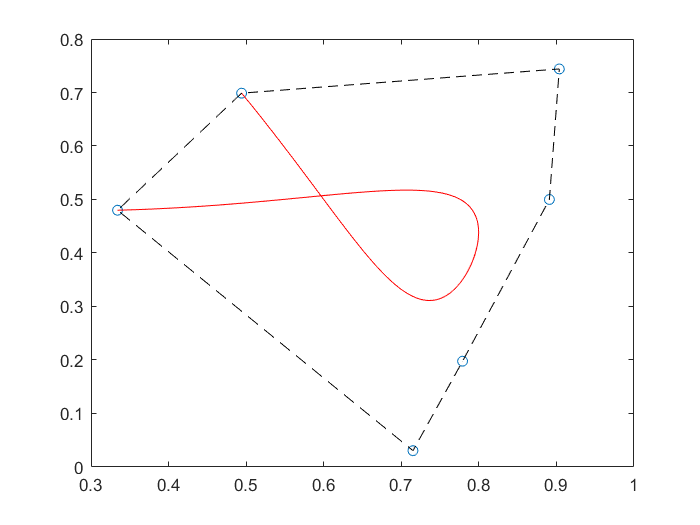

h =   3×1 Line array:

  Line
  Line
  Line


n = 5; % # of points-1, try varying this from 2 to 30
x = rand(n+1,1); y = rand(n+1,1); % Generate random points to fit around
bc = poly(-ones(1,n)); % compute binomial coefficients, 
t = linspace(0,1)'; B=[]; % build blending functions
for i=1:n+1 % really 0:n
B(:,i) = bc(i)*t.^(i-1).*(1-t).^(n-i+1); % blending
end % for

P = B*[x y]; % compute polynomial
K = convhull(x,y); % find the convex hull
xb = x(K); yb = y(K);
h = plot(x,y,'o',P(:,1),P(:,2),'r',xb,yb,'k--') % check it

# Bezier cubices using Kronecker tensor products

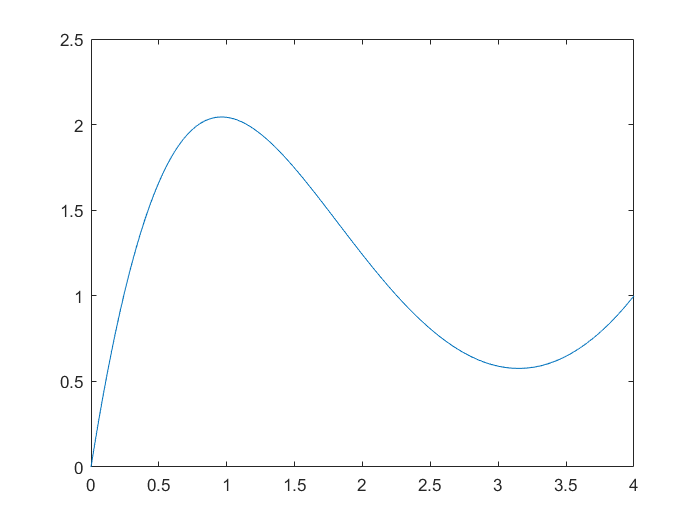

pt1=[0;0]; pt2=[1;5]; pt3=[2;-1]; pt4=[4;1]; % Take 4 arbitrary basis points
t = linspace(0,1);
% Form linear combination of 4 cubics: (1 − t) 
pts = kron((1-t).^3,pt1) + kron(3*(1-t).^2.*t,pt2) + ...
      kron(3*(1-t).*t.^2,pt3) + kron(t.^3,pt4);
plot(pts(1,:), pts(2,:))